% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

% set the degree
deg =  14;
% Define powers 
powers = 0:deg;

x = x_given(1:20:end);
y = y_given(1:20:end);

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);   
   % Find the polynomial coefficients with gramshmidt
   [Q,R] = gschmidt(Mp);
   Ag = R\Q'*y;
   % Find the polynomial coefficients with modified gramshmidt
   [Q,R] = mgschmidt(Mp);
   Am = R\Q'*y;
   % Find the polynomial coefficients with hourseholder
   [Q,R] = householder(Mp);
   Ah = R\Q'*y;

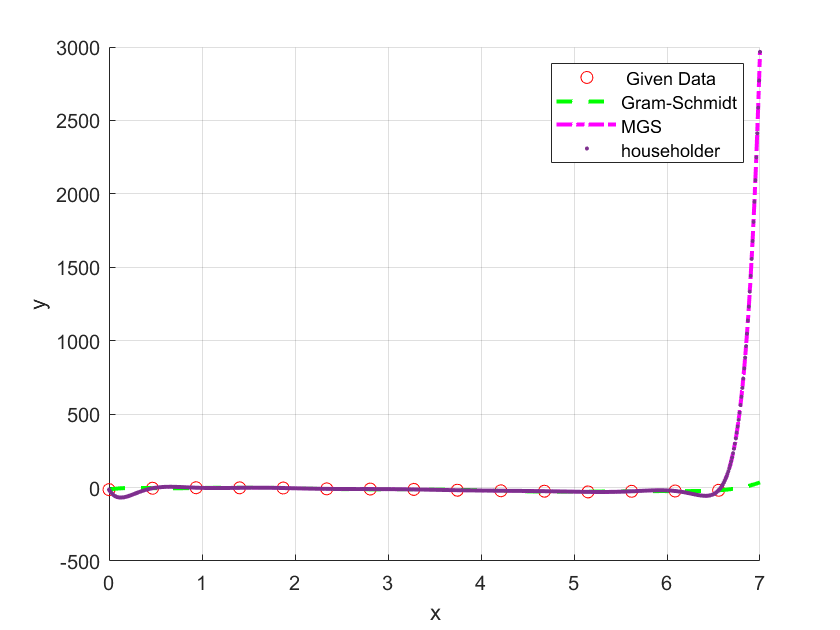

   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:0.01:7;
   x_new = x_new';
   
   fg = zeros(length(x_new),1);
   fm = zeros(length(x_new),1);
   fh = zeros(length(x_new),1);
  
   for I = 1:length(powers)
       fg = fg + Ag(I)*x_new.^powers(I);   
       fm = fm + Am(I)*x_new.^powers(I);
       fh = fh + Ah(I)*x_new.^powers(I);
   end
   %plots
   figure(1)
   hold on
   plot(x,y,'ro')
   plot(x_new,fg,'g--','Linewidth',2)
   plot(x_new,fm,'m-.','Linewidth',2)
   plot(x_new,fh,'.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Gram-Schmidt','MGS','householder')
   grid on

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 powers = 0:n;
 for i = 1:length(powers)
     M(:,i) = x.^powers(i);
 end
end

function [Q,R] = householder(A)
   % Write your code here.
   [m,n]=size(A);
   R=A;
   Q = eye(m);
   for j=1:n
       norm1 = norm(R(j:end,j));
       s = -sign(R(j,j));
       u1 = R(j,j)-s*norm1;
       V = R(j:end,j)/u1;
       V(1) = 1;
       t = -s*u1/norm1;      
       R(j:end,:) = R(j:end, :)-(t*V)*(V'*R(j:end,:));
       Q(:,j:end) = Q(:,j:end) - (Q(:,j:end)*V)*(t*V)';
   end
end

function [Q,R] = mgschmidt(A)
   % Write your code here.
   %this is based on the algorithm given in the tutorial
   [m,n]=size(A);
   Q=zeros(m,n);
   R=zeros(n,n);
   for i=1:n
       v(:,i)=A(:,i);
   end
   for i=1:n
       R(i,i)=norm(v(:,i));
       Q(:,i)=v(:,i)/R(i,i);
       for j=i+1:n
           R(i,j)=Q(:,i)'*v(:,j);
           v(:,j)=v(:,j)-R(i,j)*Q(:,i);
       end
   end
end

function [Q,R] = gschmidt(A)
   % Write your code here.
   % based on the algorithm introduced in tutorial 
   [m,n]=size(A);
   Q = zeros(m,n);
   R = zeros(n,n);
   for j = 1:n
       v=A(:,j);
       for i = 1:j-1
           R(i,j)=Q(:,i)'*A(:,j);
           v=v-R(i,j)*Q(:,i);
       end
       R(j,j)=norm(v);
       Q(:,j)=v/R(j,j);
   end
   end